# MuonLifetimeFitsBellevue

Imports QuarkNet counts v time histogram of muon lifetime study and refits with and without weights. Imports candidates and fits for lifetime with maximum likelihood method. See [https://www.mathworks.com/help/stats/examples/curve-fitting-and-distribution-fitting.html](https://www.mathworks.com/help/stats/examples/curve-fitting-and-distribution-fitting.html) for a description of the histogram fitting versus maximum likelihood fitting.

Here is the original histogram (plot.png) created by the QuarkNet muon lifetime analysis:

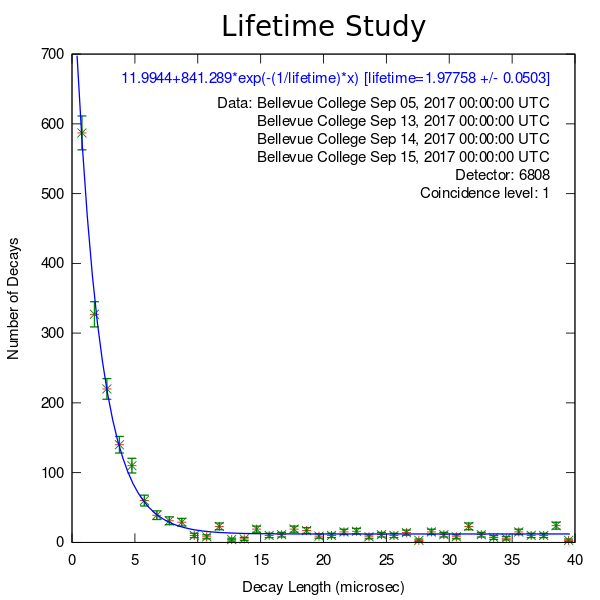

Script for importing data from the following text file:

### Read in the histogram file

Initialize variables.

filename = './fermilab_test_array_data/frequencyOut.txt';
delimiter = '\t';

Format for each line of text.

formatSpec = '%f%f%*s%[^\n\r]';

Open the text file.

fileID = fopen(filename,'r');

Read columns of data according to the format.

This call is based on the structure of the file used to generate this code. If an error occurs for a different file, try regenerating the code from the Import Tool.

dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter, 'TextType', 'string',  'ReturnOnError', false);

Close the text file.

fclose(fileID);

Allocate imported array to column variable names.

Time = dataArray{:, 1};
Counts = dataArray{:, 2};

Clear temporary variables

clearvars filename delimiter formatSpec fileID dataArray ans;

###  Plot the histogram data assuming Poisson distributed errors.

errorbar(Time,Counts,Counts.^(1/2),'.')
title('Quarknet muon decay candidate lifetime distribution')
xlabel('Decay time (microseconds)');ylabel('Counts')

### Fit the plot to exponential decay plus constant accidental background using `nlinfit.`

Define model function: a constant accidental background plus an exponential. b is a set of parameters.

modelfun = @(b,t)(b(1)+b(2)*exp(-t/b(3)));

Define weights for fit.  The variance on the count in each bin is count itself.

weights = Counts.^(-1/2);% variance on conunt in each bin is count itself

Initialize/guess starting values for fit parameters. Time units are microseconds so use known muon lifetime for lifetime parameter.

b0=[1,Counts(1),2];

Fit the histogram data passing to `nlinfit` the data, the model function name, intial parameter values, and weights.

[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(Time,Counts,modelfun,b0, 'Weights', weights);

Print parameters and standard errors.

beta

beta =      1   404     2


sqrt(diag(CovB))

ans =    NaN
   NaN
   NaN


Superpose the fit on the histogram

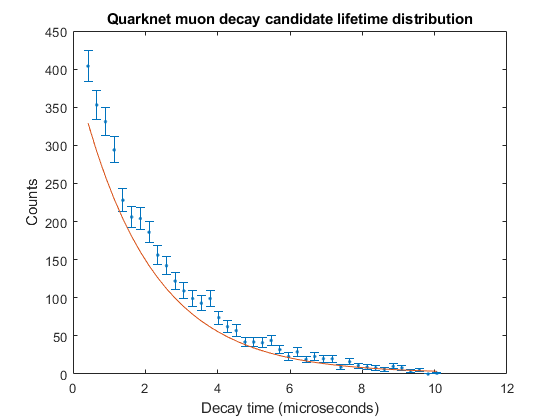

Predicted=modelfun(beta,Time);
hold on
plot(Time,Predicted)

Repeat fit but unweighted.

weights = ones(1,length(Counts))';
[beta,R,J,CovB,MSE,ErrorModelInfo] = nlinfit(Time,Counts,modelfun,b0, 'Weights', weights);
beta

beta =     0.5423  488.8145    2.0765


sqrt(diag(CovB))

ans =     2.3877
    6.8347
    0.0556


Superpose this too on the plot.

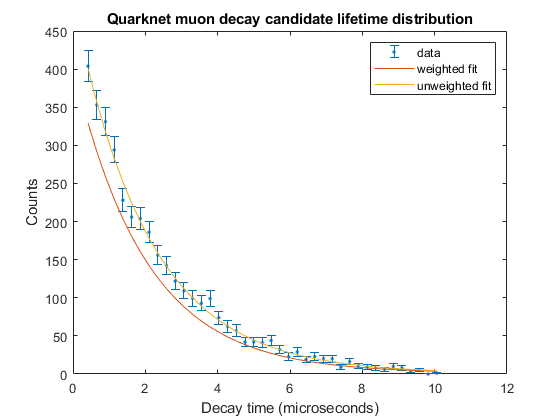

predicted=modelfun(beta,Time);
hold on
plot(Time,predicted)
legend('data','weighted fit','unweighted fit')
hold off

Get actual data behind the histogram, the candidate decay times.

filename = ['./fermilab_test_array_data/lifetimeOut.txt'];
delimiter = {'\t',',',' '};
startRow = 2;
formatSpec = '%f%f%f%f%f%f%f%f%*s%[^\n\r]';
fileID = fopen(filename,'r');
dataArray = textscan(fileID, formatSpec, 'Delimiter', delimiter,... 
    'TextType','string', 'HeaderLines' ,startRow-1, 'ReturnOnError', false,...
    'EndOfLine', '\r\n');
fclose(fileID);
channelNumb = dataArray{:, 1};
JulianDay = dataArray{:, 2};
Decaylength = dataArray{:, 3}; % microseconds
StartDecay = dataArray{:, 4}; % fraction of julian day
EndDecay = dataArray{:, 5};
FirstSignal = dataArray{:, 6};
SecondSignal = dataArray{:, 7};
DecayNumber = dataArray{:, 8};
clearvars filename delimiter startRow formatSpec fileID dataArray ans;

Make a histogram of the decay lengths as a probability distribution. (Sum of entries = 1)

h=histogram(Decaylength,'Normalization','probability'); hold on

Fit decay times with maximum likelihood method using custom probability distribution. See example at

[https://www.mathworks.com/help/stats/examples/fitting-custom-univariate-distributions.html](https://www.mathworks.com/help/stats/examples/fitting-custom-univariate-distributions.html) . To see what mle does, use the command

>>type mle

to find it calls fitdist for custom distributions. The distribution has only two parameters as it is normalized. The function mle returns 95% confidence intervals. 

range0=min(Decaylength);range1=max(Decaylength);range=range1-range0; % range of times

Define model probability distribution function normalized over the range of times observed.

pdfmuonlifetime = @(x,b2,b3) ((1-b2)+b2*exp(-x/b3))/((1-b2)*range+b2*b3*( exp(-range0/b3) -exp(-range1/b3) ));

Initial (starting) values for the parameters.

startb2=0.5;startb3=2.;
start = [ startb2 startb3];

Enforce lower and upper bounds for the parameters.

lb = [.001 1];
ub = [ 1 3];

Call `mle` (maximum likelihood estimator) sending data, model function name, initial parameter values, and parameter bounds.

We catch the parameter estimates `parmEsts` and parameters confidence intervals `pci.`

[paramEsts,pci] = mle(Decaylength, 'pdf',pdfmuonlifetime, 'start',start,...
    'lower',lb, 'upper',ub)

paramEsts =     1.0000    2.0994


pci =     0.9944    1.9717
    1.0056    2.2271


To get the standard errors of the parameters, call `mlecov` to get the covariance matrix and use diagonal elements.

acov = mlecov(paramEsts,Decaylength,'pdf',pdfmuonlifetime)

acov =     0.0000    0.0001
    0.0001    0.0042


sqrt(diag(acov))

ans =     0.0029
    0.0652


Compare `mle` fit to binned data. We simply overlay the fitted pdf muliplied by a bin width atop the binned probabilty histogram, rather than integrate the pdf over each bin which would be a more precise comparison.

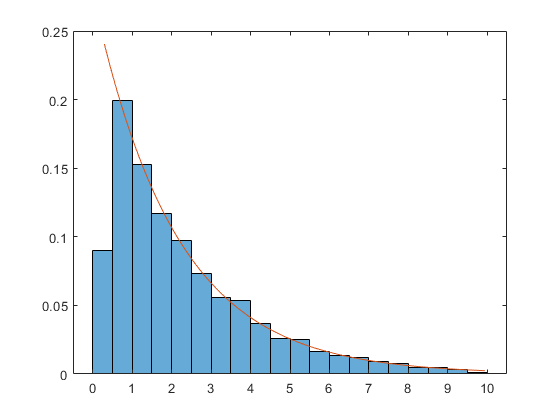

t=[range0:range/500:range1];
calculated = pdfmuonlifetime(t,paramEsts(1),paramEsts(2));
plot(t,calculated*(h.BinEdges(2)-h.BinEdges(1)))

Check normalization (crude integration)

tot= sum(calculated)*range/501

tot = 1.0027